# some numbers.

all times are in [ms]

dt  = 2;
tmax = 1000;
tmin = -200;
fs = 1/dt;
len_sample = floor((tmax-tmin)*fs);
t = linspace(tmin, tmax, len_sample);
N2_width = 200;
jitters = [0 20:20:260];
num_trails = 100;

freqs = logspace(log10(2), log10(60), 30);


## generating base wave

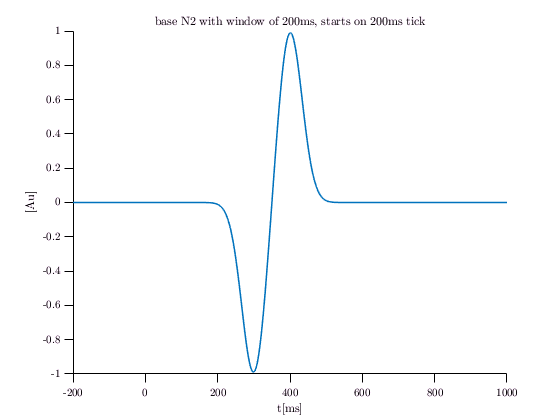

n1 = N200Generator(fs, tmin, tmax, N2_width);
n2 = circshift(n1, [1,-30*fs]);
% baseN2 = (n1-n2)*2;
s = N2_width/2/3;
baseN2 = BiPolarGenerator(t, N2_width, 200);

%baseN2 =n1;

figure;
plot(t, baseN2 )
xlabel t[ms]
ylabel [Au]
title 'base N2 with window of 200ms, starts on 200ms tick';

## The spectrum of the original basic raw data

[p,pha] = getPowerSpectra(baseN2,dt, freqs);

% helperCWTTimeFreqPlot(p, t, freqs, 'surf', )
show_spectrum(p, t, freqs, 'surf', 'basic bipolar spectrum', false)

hold on
yyaxis right
plot(t, baseN2 , 'k', 'LineWidth',2)
xlabel Time[ms]
yticks([])
% title 'base N2 with window of 200ms, starts on 200ms tick';

## generating jittered data

trials = zeros(length(t), length(jitters), num_trails);
for ii = 1:length(jitters)
    trials(:,ii,:) = N200matWithJitter(baseN2, num_trails, jitters(ii)*fs);
end



calc erps data

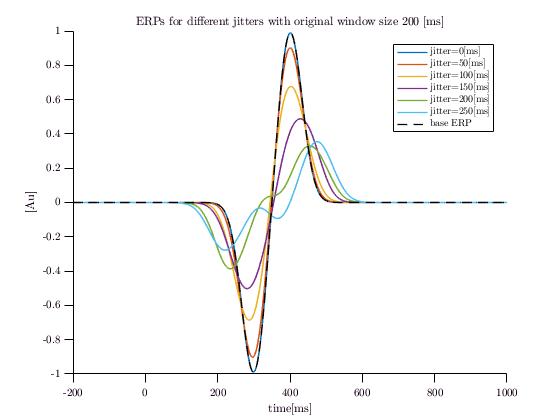

erps = mean(trials,3)';

% plotting all erps
figure;
hold on
plot(t,erps')
plot(t,baseN2,'k--')
xlabel time[ms]
ylabel [Au]
hold off
title(sprintf('ERPs for different jitters with original window size %d [ms]', N2_width));


legend_str = cellstr(num2str(jitters', 'jitter=%-d[ms]'));
legend_str_all = [legend_str; {'base ERP'}];
legend(legend_str_all);

## plotting trials with ERP data

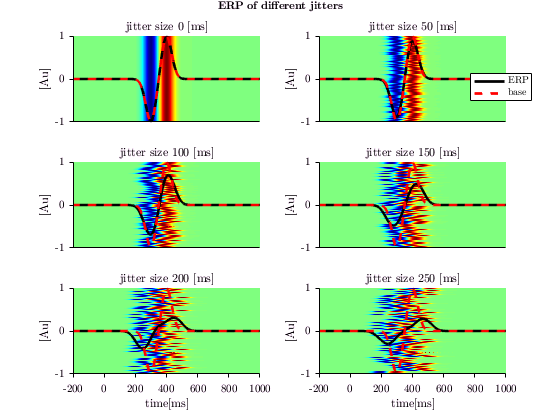

%% plot graph of each ERP with its trials
figure;
for ii = 1:length(jitters)
    % plotting all erps
    subplot(ceil(length(jitters)/2),2,ii);
    %     figure
    
    imagesc(t, [-1, 1], squeeze(trials(:,ii,:))');
    hold on
    plot(t, erps(ii,:), 'linewidth',2,'color','k');
    plot(t, baseN2 , 'r--', 'linewidth',2)
    
    axis xy
    caxis([min(trials(:)), max(trials(:))])
    set(gca,'XTick',[]);
    ylabel [Au]
    colormap jet
    title(sprintf('jitter size %d [ms]', jitters(ii)));
    hold off
end
hl = legend({'ERP', 'base'});
hl.Position = [0.84 0.76 hl.Position(3:4)];
xlabel time[ms]
set(gca, 'XTickMode', 'auto');

ax = subplot(ceil(length(jitters)/2),2,length(jitters)-1);
xlabel time[ms]
set(ax, 'XTickMode', 'auto');

title_subplots('ERP of different jitters')

## Subtracting ERPs

sub_trials = zeros(size(trials));
for ii = 1:length(jitters)
    for jj = 1:num_trails
        %         sub_trials(ii,,:) = bsxfun(@minus, trials(ii,:,:), erps(ii,:)');
        sub_trials(:,ii,jj) = squeeze(trials(:,ii,jj)) - erps(ii,:)';
    end
end

## plotting sub-trials with ERP 

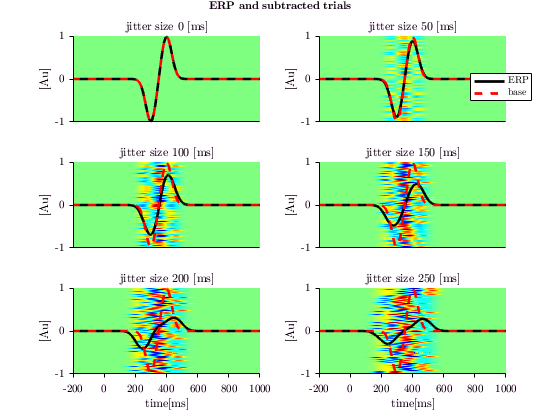

%% plot graph of each ERP with its subtracted trials
figure;
for ii = 1:length(jitters)
    % plotting all erps
    subplot(ceil(length(jitters)/2),2,ii);
    %     figure
    
    imagesc(t, [-1, 1], squeeze(sub_trials(:,ii,:))');
    hold on
    plot(t, erps(ii,:), 'linewidth',2,'color','k');
    plot(t, baseN2 , 'r--', 'linewidth',2)
    
    axis xy
    caxis([min(sub_trials(:)), max(sub_trials(:))])
    set(gca,'XTick',[]);
    ylabel [Au]
    colormap jet
    title(sprintf('jitter size %d [ms]', jitters(ii)));
   
    hold off
end

hl = legend({'ERP', 'base'});
hl.Position = [0.84 0.76 hl.Position(3:4)];
xlabel time[ms]
set(gca, 'XTickMode', 'auto');

ax = subplot(ceil(length(jitters)/2),2,length(jitters)-1);
xlabel time[ms]
set(ax, 'XTickMode', 'auto');


title_subplots('ERP and subtracted trials')

## spectral analysis

originals_freq_power = zeros([length(jitters) length(freqs) length(t)]);
subtrials_freq_power = originals_freq_power;
total_freq_phase = zeros([length(jitters) length(freqs) length(t) num_trails]);
erps_freq_power = getPowerSpectra(erps,dt, freqs); %freq-time-channel
% erps_freq_power = shiftdim(erps_freq_power,2); %channel-freq-time

for ii = 1:length(jitters)
    [power,ph] = getPowerSpectra(squeeze(trials(:,ii,:))',dt, freqs);
    originals_freq_power(ii,:,:) = mean(power,3);
    total_freq_phase(ii,:,:,:) = ph;
    [power,~] = getPowerSpectra(squeeze(sub_trials(:,ii,:))',dt, freqs);
    subtrials_freq_power(ii,:,:) = mean(power,3);    
end
diff_original_subtracted_trials = originals_freq_power - subtrials_freq_power;



Time Freq Plot

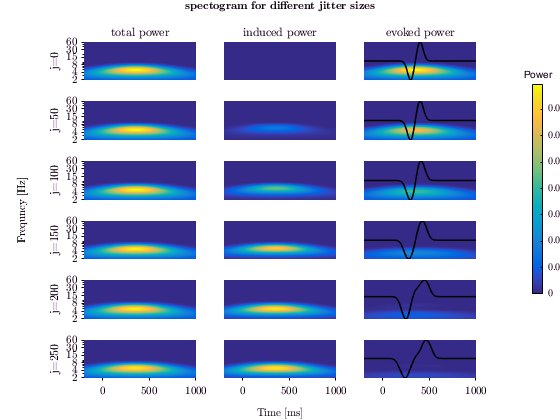

figure;
datas2show = zeros(size(originals_freq_power, 2), size(originals_freq_power, 3), size(originals_freq_power, 1)*3);
datas2show(:,:,1:3:end) = shiftdim(originals_freq_power,1);
datas2show(:,:,2:3:end) = shiftdim(subtrials_freq_power,1);
datas2show(:,:,3:3:end) = shiftdim(diff_original_subtracted_trials,1);
overlap_data = zeros(size(datas2show,2), size(datas2show,3));
overlap_data(:, 1:3:end) = nan;
overlap_data(:, 2:3:end) = nan;
overlap_data(:, 3:3:end) = erps(:,:)';
% title_freq = sprintf('subject=%d, resampled (%d X %d)', subj_ind, m, n);
show_powers_tight(t, freqs, datas2show, ...
3, 'spectogram for different jitter sizes', 'Power', overlap_data, ...
compose('j=%d', jitters), ...
true, {'total power', 'induced power', 'evoked power'}, [] , 0.1, 0.15)
colormap(parula(128))

% colormap jet
%title_y, col_titles, gap,  marg_h, marg_w)


## Time Freq Plot

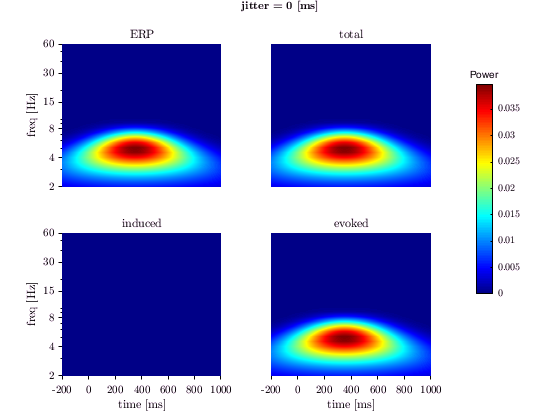

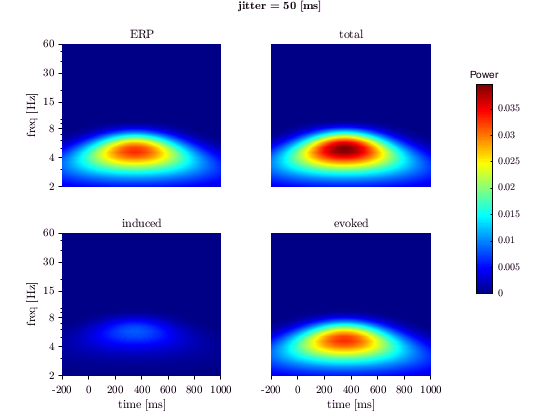

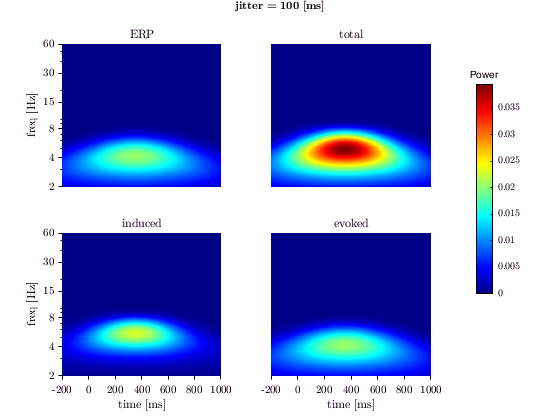

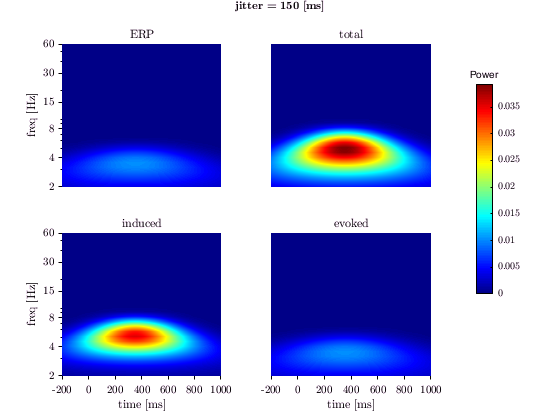

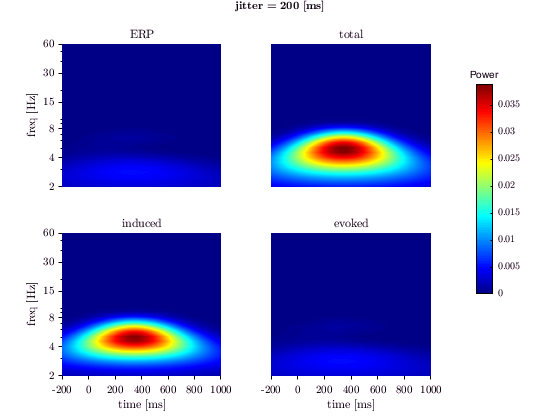

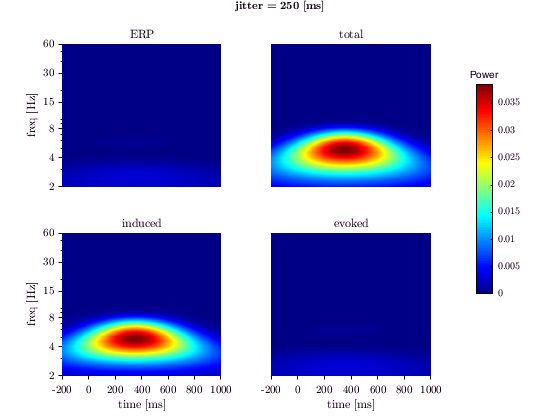


plotType = 'surf';
for ii = 1:length(jitters)
    % ii=4;
    h = figure;
    subplot(2,2,2)
    show_time_freq(squeeze(originals_freq_power(ii,:,:)), t, freqs, {'total'}, plotType)
    set(gca,'XTick',[]);
    xlabel ''
    set(gca,'YTick',[]);
    ylabel ''
    Ca = caxis;
    subplot(2,2,1)
    show_time_freq(squeeze(erps_freq_power(:,:,ii)), t, freqs, 'ERP', plotType)
    xlabel ''
    set(gca,'XTick',[]);
    caxis(Ca)
    subplot(2,2,3)
    show_time_freq(squeeze(subtrials_freq_power(ii,:,:)), t, freqs, {'induced'}, plotType)
    caxis(Ca)
    subplot(2,2,4)
    show_time_freq(squeeze(diff_original_subtracted_trials(ii,:,:)), t, freqs, {'evoked'}, plotType)
    set(gca,'YTick',[]);
    ylabel ''
    caxis(Ca)
    
 
    h = colorbar;
    title(h,'Power');
    set(h, 'Position', [.85 0.3 0.03 0.5])
    
    for jj=1:4
      pos=get(subplot(2,2,jj), 'Position');
      set(subplot(2,2,jj), 'Position', [0.85*pos(1) 0.95*pos(2) 0.85*pos(3) pos(4)]);
    end
    
    
    %title for the figure
    add_subplot_title(sprintf('\\bf jitter = %d [ms]', jitters(ii)));

%     saveas(h, sprintf('./graphs/MATLAB_cwtft/spectogram_with_jitter_%dms.jpg', jitters(ii))); 
end

## phases

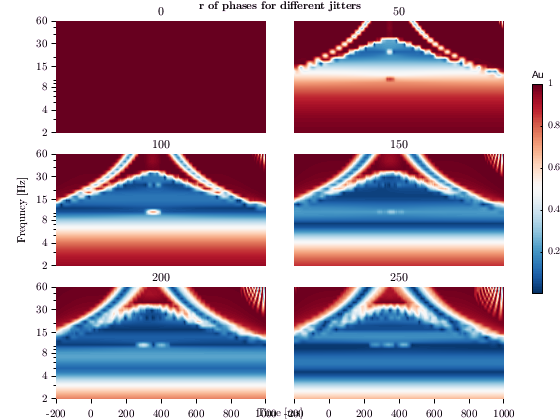

figure;
show_powers_tight(t,freqs, shiftdim(abs(circ_r(total_freq_phase(:,:,:,:),[],[],4)),1), 2, 'r of phases for different jitters', 'Au',[], jitters)

## Hilbert phase

phase_hilbert = get_hilbert_phase(trials, 4, 8, dt*1000);
phase_stds = abs(circ_std(phase_hilbert,[],[],3));
phase_mean = circ_mean(phase_hilbert,[],3);

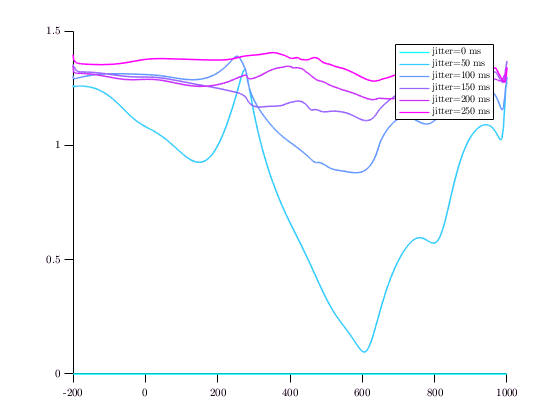

figure;
h = plot(t,phase_stds);
legend(cellstr(num2str(jitters', 'jitter=%d ms')))
set(h, {'color'}, num2cell(cool(length(h)),2));

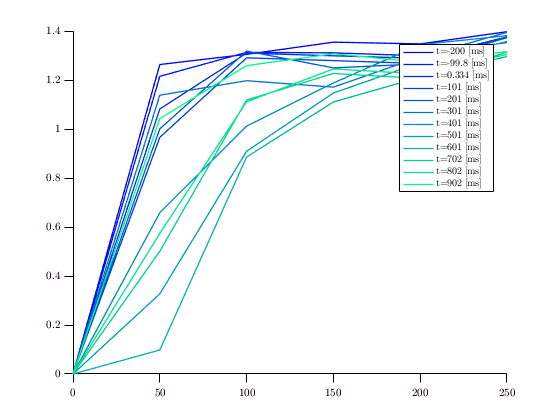

% set(gca, 'ColorOrder', [0.5 0.5 0.5; 1 0 0], 'NextPlot', 'replacechildren');


h = plot(jitters,phase_stds(1:50:end,:)');
legend(cellstr(num2str(t(1:50:end)', 't=%.3g [ms]')))
set(h, {'color'}, num2cell(winter(length(h)),2));

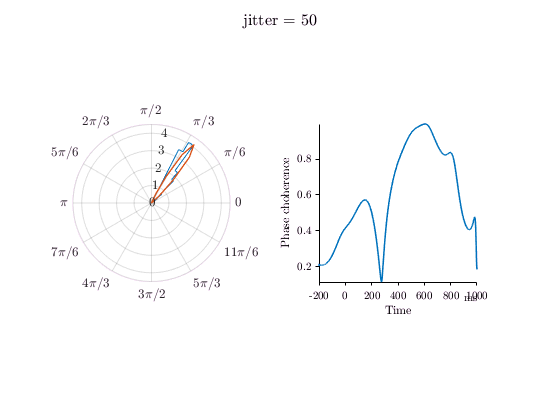

theta_phases_r = circ_r(phase_hilbert,[],[],3);
u = t > -300;
subj = 2;

[~,t_ind_subj] = max(theta_phases_r(:,subj));
subj_theta_phases = squeeze(phase_hilbert(t_ind_subj,subj,:));
% t_ind_subj = 100;
[thetahat, kappa] = circ_vmpar(subj_theta_phases);
[p,a]=circ_vmpdf([], thetahat, kappa);


figure
subplot(1,2,1)
polarhistogram(subj_theta_phases, 20,'Normalization','pdf',...
    'FaceAlpha',0, 'DisplayStyle','stairs');
pax = gca;
pax.ThetaAxisUnits = 'radians';
hold on
polarplot(a,p)

subplot(1,2,2)
%varplot(t,squeeze(mean(theta_phases_r(u,:,:),2)))
plot(t(u),theta_phases_r(u,subj))
axis tight
xlabel Time
axis square
ylabel 'Phase choherence'

xunits ms %replace
suptitle(sprintf('jitter = %d',jitters(subj)))


freq_mean = mean([4.5,8]);
jitter_estimate = sqrt(1-besseli(1,kappa)/besseli(0,kappa)) / freq_mean * 1e3;

fprintf('jitter estimate is %.0f [ms] at t ~ %.0f [ms]\n', jitter_estimate , t(t_ind_subj))

jitter estimate is 11 [ms] at t ~ 605 [ms]


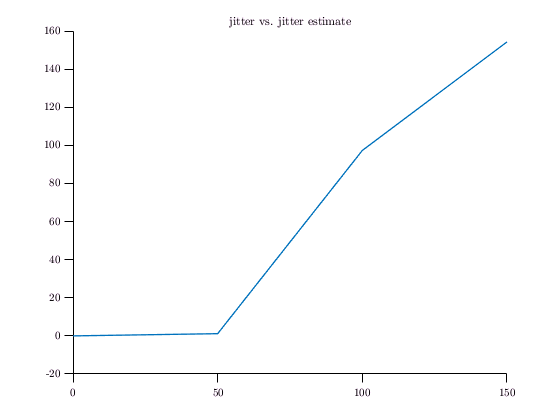


jitter_estimates = jitters*0;
kappas = jitters*0;
for subj = 1:length(jitters)

    [~,t_ind_subj] = max(theta_phases_r(:,subj));
    subj_theta_phases = squeeze(phase_hilbert(t_ind_subj,subj,:));
    % t_ind_subj = 100;
    [thetahat, kappa] = circ_vmpar(subj_theta_phases);
    
    freq_mean = mean([4.5,8]);
    % jitter_estimates(subj) = sqrt(1-besseli(1,kappa)/besseli(0,kappa)) / freq_mean * 1e3;
    %jitter_estimates(subj) = (1-theta_phases_r(t_ind_subj,subj))/2/theta_phases_r(t_ind_subj,subj)^2;
    jitter_estimates(subj) = circ_var(subj_theta_phases) * pi/2/freq_mean * 1e3;
    kappas(subj) = kappa;
    % jitter_estimates(subj) = 1/sqrt(kappa) / pi *2 / freq_mean * 1e3;

end
figure;
plot(jitters(jitters<200),jitter_estimates(jitters<200))
title 'jitter vs. jitter estimate'

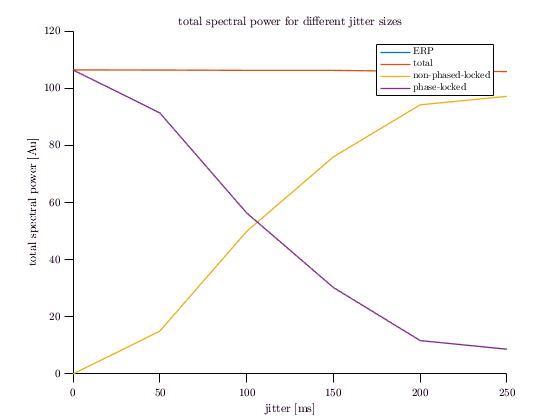

%% compare jitter size to sum of spectral information
tot_freq_sum = @(X) squeeze(sum(sum(X,2),3));
tot_erp = squeeze(sum(sum(erps_freq_power,1),2));
tot_orig = tot_freq_sum(originals_freq_power);
tot_sub = tot_freq_sum(subtrials_freq_power);
tot_diff = tot_freq_sum(diff_original_subtracted_trials);

figure;
plot(jitters, [tot_erp, tot_orig, tot_sub, tot_diff]');
% plot(jitters, [ tot_orig, tot_sub, tot_diff]');
title 'total spectral power for different jitter sizes'
xlabel 'jitter [ms]'
ylabel 'total spectral power [Au]'
legend({'ERP', 'total', 'non-phased-locked', 'phase-locked'})

% legend({'total', 'non-phased-lock', 'phased-lock'})


function add_subplot_title(title)
ha = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text(0.5, 1,title,'HorizontalAlignment' ,'center','VerticalAlignment', 'top');
end

function show_time_freq(amp,time,freq, title_str, plotType)
if strncmpi(plotType,'surf',1)
    surf(time,freq,double(amp))%,'edgecolor','none');
    view(0,90);
    shading interp;
    colormap jet;
    
elseif strcmpi(plotType,'contourf')
    contourf(time,freq,amp);
    colormap(parula(128));
end
axis tight;
grid on;
title(title_str)
xlabel('time [ms]'); ylabel('freq [Hz]');
set(gca,'yscale','log')
%     set(gca,'YLim',[0 4])
set(gca,'YTick',round(logspace(log10(min(freq)), log10(max(freq)), 6)))
end